#### Check how autorcorrelation graph is affected by removing outlier data (ten minutes of blackout).

tic;
legendList = {};
maxLag = 60;
grid = 'spain_mallorca';
[years,months] = selectTimePeriod(grid)

years = 2019

months = 9

for year = years
    for month = months
        if dataExists(grid,year,month)
            filename = selectInput(grid,year,month,0)
            fautocorr = readmatrix(strcat(filename,'_fautocorr.txt'));
        else
            continue;
        end
        p = plot(fautocorr);
        if strcmp(grid,'nrldc')
        elseif year == 2018
            p.LineStyle = ':';
            p.LineWidth = 1;
            p.Color = 'b';
        elseif year == 2019
            p.LineStyle = ':';
            p.LineWidth = 1;
            p.Color = 'm';
        elseif year == 2020
            p.LineStyle = '--';
            p.LineWidth = 1;
            p.Color = 'r';
        elseif year == 2021
            p.LineStyle = ':';
            p.LineWidth = 3;
            p.Color = 'g';
        end
        if length(num2str(month)) == 1
            strMonth = ['0' num2str(month)];
        else
            strMonth = num2str(month);
        end
        legendList = [legendList,[grid '_' num2str(year) '_' strMonth '_0']];
        hold on;
    end
end

filename = 'processedData/data_spain_mallorca_2019_09_0'

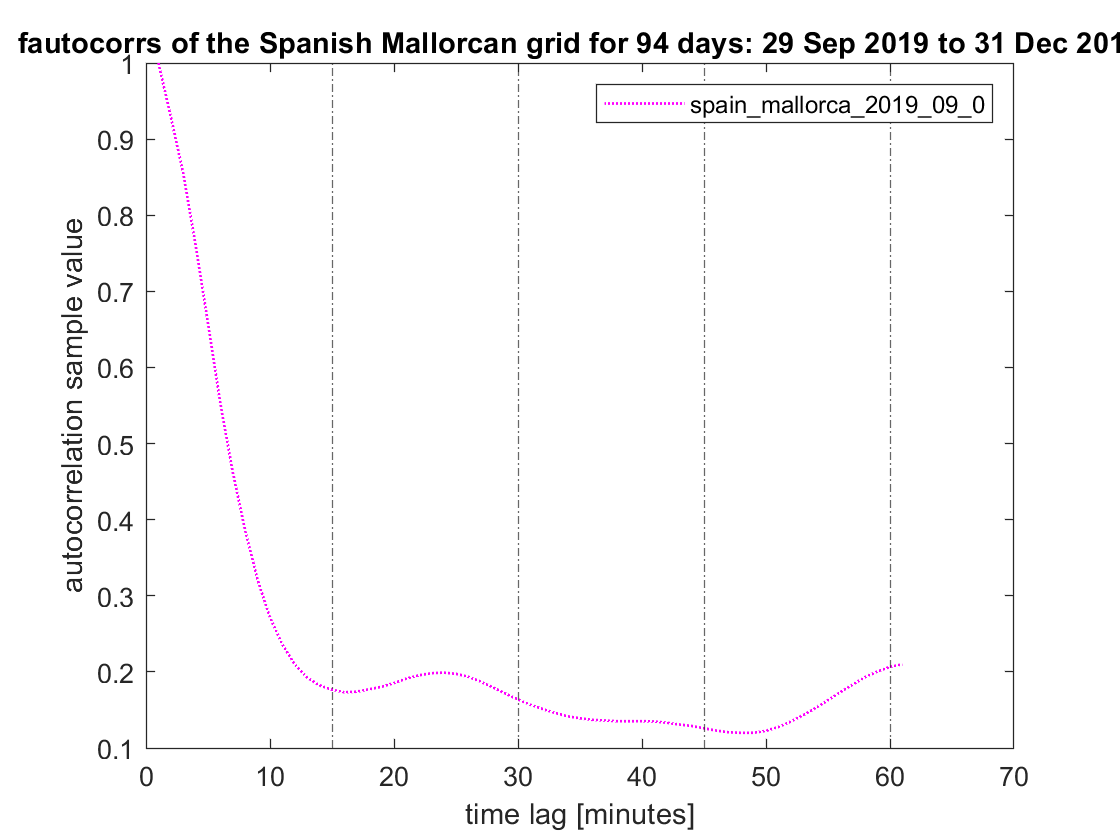


hold off;
ylabel('autocorrelation sample value')
xlabel('time lag [minutes]')

for x = 15:15:maxLag
    xline(x,'-.');
end

labelAutcorrelationPlot(grid, legendList);


toc;

Elapsed time is 0.635500 seconds.
